clc
clear
n = 10;
N = n^2;
A = gallery('poisson', n);
fprintf(['\nDimensione matrice dei coefficienti A: '...
       '%u x %u \n\n'],N,N);


Dimensione matrice dei coefficienti A: 100 x 100 



disp(full(A(1:5, 1:5)));

     4    -1     0     0     0
    -1     4    -1     0     0
     0    -1     4    -1     0
     0     0    -1     4    -1
     0     0     0    -1     4



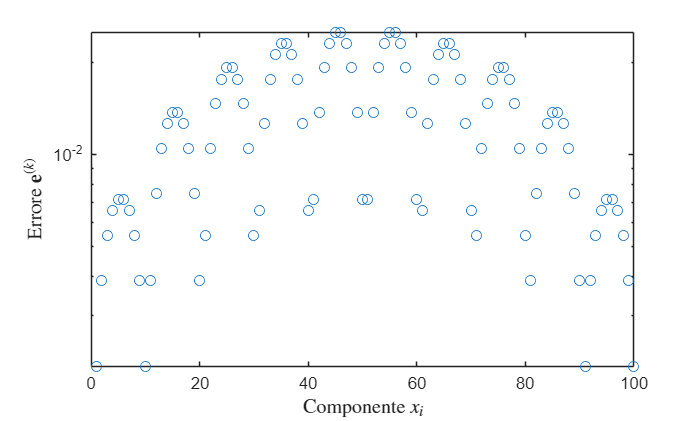

b = sum(A,2);
% Soluzione esatta del sistema
xExact = ones(N,1);

% I tentativo - Metodo di jacobi con parametri di default
[xJM1,flagJM1,relresJM1,iterJM1,resvecJM1] = jacobi(A,b);
% Calcolo dell'errore assoluto
errJM1 = abs(xExact - xJM1);
% Rappresentazione grafica errore assoluto
figure(1)
semilogy(errJM1, 'o');
ylabel('Errore $\mathbf{e}^{(k)}$', 'Interpreter','latex','FontSize',12);
xlabel('Componente $x_{i}$', 'Interpreter','latex','FontSize',12);

if flagJM1 == 1
fprintf("jacobi si è fermato all'iterazione %u senza " + ...
        "raggiungere la tolleranza desiderata %0.2g " + ...
        "poiché il numero massimo di iterazioni %u " + ...
        "è stato raggiunto. L'ultima iterazione ha residuo relativo pari a %0.2g.\n", ...
        iterJM1, 1e-6, 100, relresJM1);
end

jacobi si è fermato all'iterazione 100 senza raggiungere la tolleranza desiderata 1e-06 poiché il numero massimo di iterazioni 100 è stato raggiunto. L'ultima iterazione ha residuo relativo pari a 0.0033.


% II tentativo - Metodo di jacobi con parametri personalizzati 
maxit = 3e5;

tJM2 = tic;
[xJM2,flagJM2,relresJM2,iterJM2,resvecJM2] = jacobi(A,b,[],maxit);
tJM2 = toc(tJM2);

if flagJM2 == 0
     fprintf("jacobi ha raggiunto la convergenza all'iterazione %u, calcolando " + ...
             "una soluzione approssimata con residuo relativo pari a %0.2g.\n",iterJM2,relresJM2);
end

jacobi ha raggiunto la convergenza all'iterazione 296, calcolando una soluzione approssimata con residuo relativo pari a 9.9e-07.


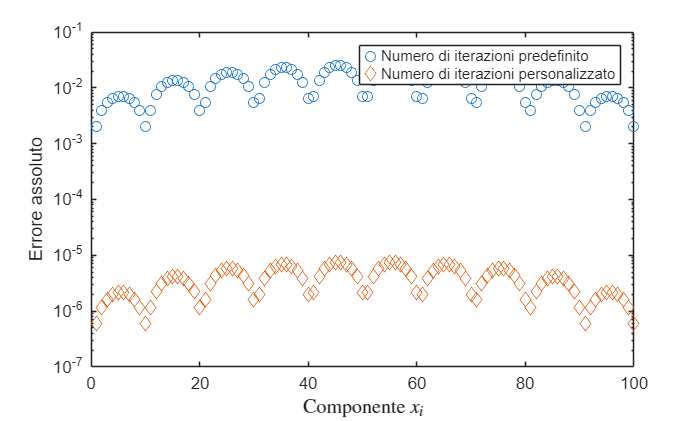

errJM2 = abs(xExact - xJM2);

figure(2)
semilogy(errJM1,'o');
hold on
semilogy(errJM2,'diamond');
ylabel('Errore assoluto');
xlabel('Componente $x_{i}$', 'Interpreter','latex','FontSize',12);
legend('Numero di iterazioni predefinito','Numero di iterazioni personalizzato');
hold off

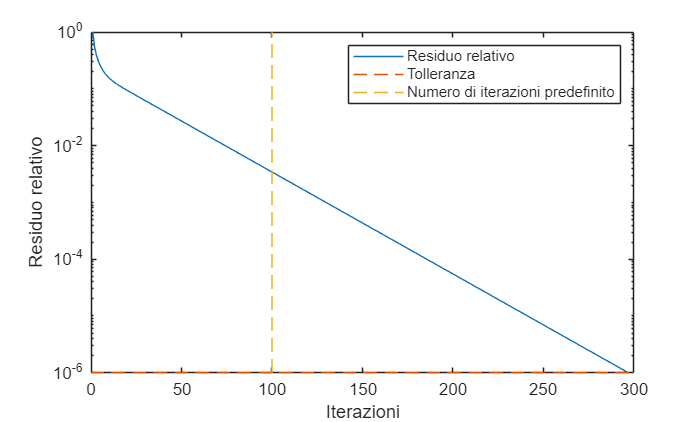

relresvecJM = resvecJM2./resvecJM2(1);

figure(3)
f=semilogy(relresvecJM);
hold on
semilogy(f.Parent.XLim,[1e-6 1e-6],'--')
semilogy([100 100], f.Parent.YLim,'--')

ylabel('Residuo relativo');
xlabel("Iterazioni");
legend('Residuo relativo','Tolleranza','Numero di iterazioni predefinito')
hold off

% Generazione array distribuiti
n = 10;

n = 10

A = distributed((gallery('poisson', n)));

Starting parallel pool (parpool) using the 'Processes' profile ...
12-Aug-2025 22:56:53: Job Queued. Waiting for parallel pool job with ID 9 to start ...
Connected to parallel pool with 2 workers.


b = sum(A,2);

% III tentativo - Metodo di jacobi con supporto agli array distribuiti
tJM3 = tic;
[xJM3,flagJM3,relresJM3,iterJM3,resvecJM3] = jacobi(A,b,[],maxit);
tJM3 = toc(tJM3);
if flagJM3 == 0
     fprintf("jacobi ha raggiunto la convergenza all'iterazione %u, calcolando " + ...
             "una soluzione approssimata con residuo relativo pari a %0.2g.\n",iterJM3,relresJM3);
end

jacobi ha raggiunto la convergenza all'iterazione 296, calcolando una soluzione approssimata con residuo relativo pari a 9.9e-07.


% speedup = tJM2/tJM3
% fprintf("Tempo di esecuzione per il metodo di jacobi classico: %f sec.", tJM2);
% fprintf("Tempo di esecuzione per il metodo di jacobi con array distribuiti: %f sec.", tJM3);
% fprintf("Speedup attribuibile alla parallelizzazione: %f", speedup);